
% Program to get the Gauss-Legendre Quadrature results (Vectorized)
clear;clc;

dbstop if error
format long e

[x]= [0.999305042	0.996340117	0.991013371	0.983336254	0.973326828	0.9610088	0.946411375	0.929569172	0.910522137...
    0.889315446	0.865999398	0.840629296	0.813265315	0.783972359	0.752819907	0.71988185	0.685236313	0.648965471...
    0.611155355	0.571895646	0.531279464	0.489403146	0.446366017	0.402270158	0.357220158	0.311322872	0.264687162...
    0.217423644	0.16964442	0.121462819	0.072993122	0.024350293	-0.024350293	-0.072993122	-0.121462819	-0.16964442...
    -0.217423644	-0.264687162	-0.311322872	-0.357220158	-0.402270158	-0.446366017	-0.489403146	-0.531279464...
    -0.571895646	-0.611155355	-0.648965471	-0.685236313	-0.71988185	-0.752819907	-0.783972359	-0.813265315...
    -0.840629296	-0.865999398	-0.889315446	-0.910522137	-0.929569172	-0.946411375	-0.9610088	-0.973326828...
    -0.983336254	-0.991013371	-0.996340117	-0.999305042];
[weight]=[0.001783281	0.004147033	0.006504458	0.00884676	0.011168139	0.013463048	0.01572603	0.017951716	0.020134823...
    0.022270174	0.024352703	0.02637747	0.028339673	0.030234657	0.032057928	0.033805162	0.035472213	0.037055129	0.038550153...
    0.039953741	0.041262563	0.042473515	0.043583725	0.044590558	0.045491628	0.046284797	0.046968183	0.047540166	0.047999389...
    0.048344762	0.048575467	0.048690957	0.048690957	0.048575467	0.048344762	0.047999389	0.047540166	0.046968183	0.046284797...
    0.045491628	0.044590558	0.043583725	0.042473515	0.041262563	0.039953741	0.038550153	0.037055129	0.035472213	0.033805162...
    0.032057928	0.030234657	0.028339673	0.02637747	0.024352703	0.022270174	0.020134823	0.017951716	0.01572603	0.013463048...
    0.011168139	0.00884676	0.006504458	0.004147033	0.001783281];
% [x]=xlsread('Gauss-Legendre Quadrature','Sheet1','b1:z1');
% [weight]=xlsread('Gauss-Legendre Quadrature','Sheet1','b2:z2');

E=191e9;               %Young’s modulus
nu=0.38;                 %poisson's ratio
k=1e9;                  %hardening parameter
b=1.5;                      %weakening scales distribution exponent (between 1 and 2)
y=1080e6;            %macroscopic yield stress
sigu=1200e6;             %ultimite stress
ff=690e6;              %bending fatigue limit
tt=428e6;                  %torsion fatigue limit

gam=b+1;              %material parameter from Chaboche law(Wohler curve exponent)

load=5e8;            %cyclic load
loadtensor= [load 0 0;0 0 0;0 0 0];
stepnumber=200;        %devide one cycle in 200 parts
f=50;                            %frequency of load
steptime=1/f/stepnumber;
delta=(b+1)/(b-1);
alp=0.5;
WF=5e6;             %dissipated energy to failure per unit volume


%---------------------3 Numerical method-----------------------------
D=0;
G = (1 - (1 - D).^(gam + 1)).^(1-alp);
D= zeros(1,1e6); %Pre-allocate memory for vectors
n=1;       %initial recording point

%---------------------to get the the first Sb-----------------------------
yield=y;
stress11=load*sin(1*2*pi/stepnumber);
m=1/3*sum(stress11+0+0);
dev1=[stress11 0 0 ;0 0 0 ;0 0 0 ]-m*diag([1,1,1]);
dev11=dev1(1,1); dev12=dev1(1,3); dev13=dev1(1,3);
dev21=dev1(2,1); dev22=dev1(2,2); dev23=dev1(2,3);
dev31=dev1(3,1); dev32=dev1(3,2); dev33=dev1(3,3);

trial11=dev11; trial12=dev12; trial13=dev13;
trial21=dev21; trial22=dev22; trial23=dev23;
trial31=dev31; trial32=dev32; trial33=dev33;
s= (x/2+1/2).^(1/(1-b)); %1*25

normtrial(1)=norm([trial11, trial12, trial13; trial21, trial22, trial23;trial31, trial32, trial33],'fro');
dev(1)=norm([dev11, dev12, dev13; dev21, dev22, dev23;dev31, dev32, dev33],'fro');
Smin = yield/normtrial(1);
s1=Smin.*s;%1*25
eta=bsxfun(@minus,bsxfun(@times,normtrial(1)/yield,s1),1); %compare normtrial with yield/s
eta(eta<0)=0; %only keep normtrials which are larger than yield/s

Sb11=bsxfun(@rdivide,trial11,bsxfun(@plus,eta,1));Sb12=bsxfun(@rdivide,trial12,bsxfun(@plus,eta,1));Sb13=bsxfun(@rdivide,trial13,bsxfun(@plus,eta,1));
Sb21=bsxfun(@rdivide,trial21,bsxfun(@plus,eta,1));Sb22=bsxfun(@rdivide,trial22,bsxfun(@plus,eta,1));Sb23=bsxfun(@rdivide,trial23,bsxfun(@plus,eta,1));
Sb31=bsxfun(@rdivide,trial31,bsxfun(@plus,eta,1));Sb32=bsxfun(@rdivide,trial32,bsxfun(@plus,eta,1));Sb33=bsxfun(@rdivide,trial33,bsxfun(@plus,eta,1));
%1*25 for each Sb element
Sbtensor=[Sb11; Sb12; Sb13; Sb21; Sb22; Sb23;Sb31; Sb32; Sb33];
normSb=sqrt(sum(Sbtensor.^2)); %sum(a) sums all the colume

% existsOnGPU(normSb)
Ws1=(bsxfun(@minus,normtrial,bsxfun(@rdivide, yield,s1))<=0).*...
    (0)+...
    (bsxfun(@minus,normtrial,bsxfun(@rdivide, yield,s1))>0).*...
    (Smin^(1-b)*(E-k)*(1+nu)*(2*E*(E+k*nu))^-1*bsxfun(@times,weight,bsxfun(@rdivide,bsxfun(@times,bsxfun(@minus,normtrial,bsxfun(@rdivide, yield,s1)),yield),s1)));


Ws=(bsxfun(@minus,normtrial,bsxfun(@rdivide, yield,s))<=0).*...
    (0)+...
    (bsxfun(@minus,normtrial,bsxfun(@rdivide, yield,s))>0).*...
    ((E-k)*(1+nu)*(2*E*(E+k*nu))^-1*bsxfun(@times,weight,bsxfun(@rdivide,bsxfun(@times,bsxfun(@minus,normtrial,bsxfun(@rdivide, yield,s)),yield),s)));
W1= sum(Ws1)
W= sum(Ws)
G = G+(1-alp)*(gam + 1)*W1/WF;
D(1)=1-(1-G.^(1/(1-alp))).^(1/(gam + 1));


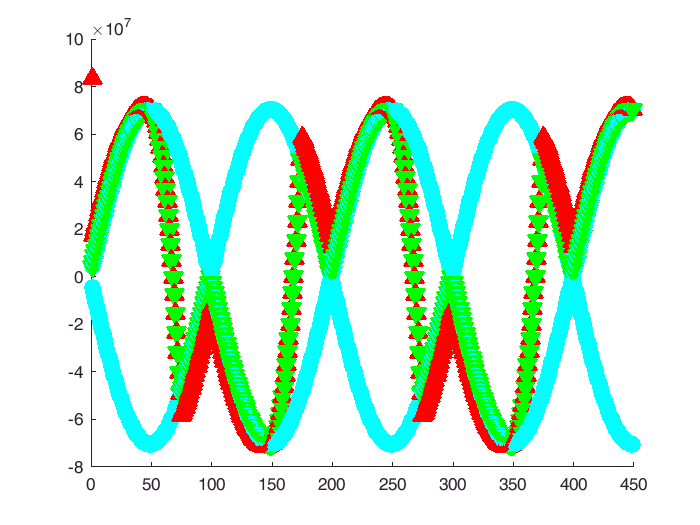

n=1;
tic;
while n<450
    stress11=load*sin(n*2*pi/stepnumber);
    m=1/3*sum(stress11+0+0);
    dev1=[stress11 0 0 ;0 0 0 ;0 0 0 ]-m*diag([1,1,1]);
    dev11=dev1(1,1); dev12=dev1(1,2); dev13=dev1(1,3);
    dev21=dev1(2,1); dev22=dev1(2,2); dev23=dev1(2,3);
    dev31=dev1(3,1); dev32=dev1(3,2); dev33=dev1(3,3);
    
    stress11=load*sin((n+1)*2*pi/stepnumber);
    m=1/3*sum(stress11+0+0);
    devn=[stress11 0 0;0 0 0;0 0 0]-m*diag([1,1,1]);
    dev11g=devn(1,1); dev12g=devn(1,2); dev13g=devn(1,3);
    dev21g=devn(2,1); dev22g=devn(2,2); dev23g=devn(2,3);
    dev31g=devn(3,1); dev32g=devn(3,2); dev33g=devn(3,3);
    
    trial11=bsxfun(@plus,Sb11,(dev11g-dev11)); trial12=bsxfun(@plus,Sb12,(dev12g-dev12));trial13=bsxfun(@plus,Sb13,(dev13g-dev13));
    trial21=bsxfun(@plus,Sb21,(dev21g-dev21)); trial22=bsxfun(@plus,Sb22,(dev22g-dev22));trial23=bsxfun(@plus,Sb23,(dev23g-dev23));
    trial31=bsxfun(@plus,Sb31,(dev31g-dev31)); trial32=bsxfun(@plus,Sb32,(dev32g-dev32));trial33=bsxfun(@plus,Sb33,(dev33g-dev33));
    trialtensor=[trial11; trial12; trial13; trial21; trial22; trial23;trial31; trial32; trial33];
    normtrial=sqrt(sum(trialtensor.^2));
    dev(n+1)=norm([dev11g, dev12g, dev13g; dev21g, dev22g, dev23;dev31g, dev32g, dev33g],'fro');
    Smin = yield/dev(n+1);
    s1=Smin.*s;%1*25
    eta=bsxfun(@minus,bsxfun(@times,normtrial/yield,s1),1); %1*25
    eta(eta<0)=0;
    
    Sb11=bsxfun(@rdivide,trial11,bsxfun(@plus,eta,1));Sb12=bsxfun(@rdivide,trial12,bsxfun(@plus,eta,1));Sb13=bsxfun(@rdivide,trial13,bsxfun(@plus,eta,1));
    Sb21=bsxfun(@rdivide,trial21,bsxfun(@plus,eta,1));Sb22=bsxfun(@rdivide,trial22,bsxfun(@plus,eta,1));Sb23=bsxfun(@rdivide,trial23,bsxfun(@plus,eta,1));
    Sb31=bsxfun(@rdivide,trial31,bsxfun(@plus,eta,1));Sb32=bsxfun(@rdivide,trial32,bsxfun(@plus,eta,1));Sb33=bsxfun(@rdivide,trial33,bsxfun(@plus,eta,1));
    %1*25 for each Sb element
    Sbtensor=[Sb11; Sb12; Sb13; Sb21; Sb22; Sb23;Sb31; Sb32; Sb33];
    normSb=sqrt(sum(Sbtensor.^2)); %sum(a) sums all the colume
    
    Ws1=(bsxfun(@minus,normtrial,bsxfun(@rdivide, yield,s1))<=0).*...
        (0)+...
        (bsxfun(@minus,normtrial,bsxfun(@rdivide, yield,s1))>0).*...
        ((E-k)*(1+nu)*(2*E*(E+k*nu))^-1*bsxfun(@times,weight,bsxfun(@rdivide,bsxfun(@times,bsxfun(@minus,normtrial,bsxfun(@rdivide, yield,s1)),yield),s1)));
    Ws=(bsxfun(@minus,normtrial,bsxfun(@rdivide, yield,s))<=0).*...
        (0)+...
        (bsxfun(@minus,normtrial,bsxfun(@rdivide, yield,s))>0).*...
        ((E-k)*(1+nu)*(2*E*(E+k*nu))^-1*bsxfun(@times,weight,bsxfun(@rdivide,bsxfun(@times,bsxfun(@minus,normtrial,bsxfun(@rdivide, yield,s)),yield),s)));
    W= sum(Ws);
    W1= sum(Ws1);
    Wdiff(n+1)=W1-W;
    G = G+(1-alp)*(gam + 1)*W1/WF;
    D(n+1)=1-(1-G.^(1/(1-alp))).^(1/(gam + 1));
    hold on;
    yield1=plot (n,yield*s1(36)^-1, 'LineStyle', 'none','LineWidth', 1, 'Marker', 'o', 'MarkerSize', 10, ...
        'MarkerEdgeColor',  'none', 'MarkerFaceColor' , 'c');
    yield1n=plot (n,-yield*s1(36)^-1, 'LineStyle', 'none','LineWidth', 1, 'Marker', 'o', 'MarkerSize', 10, ...
        'MarkerEdgeColor',  'none', 'MarkerFaceColor' , 'c');
    Trial1=plot (n,sign(trial11(36))*normtrial(36),'LineStyle', 'none','LineWidth', 1,'Marker', '^', 'MarkerSize', 10, ...
        'MarkerEdgeColor','r', 'MarkerFaceColor','r');
    Sb1=plot (n,sign(trial11(36))*normSb(36),'LineStyle', 'none','LineWidth', 1,'Marker', 'v', 'MarkerSize', 10, ...
        'MarkerEdgeColor','g', 'MarkerFaceColor','g');
    %             yield8=plot (n,yield*s1(51)^-1,'LineStyle', 'none','LineWidth', 1,'Marker', 'o', 'MarkerSize', 10, ...
    %                 'MarkerEdgeColor', 'none', 'MarkerFaceColor', 'b');
    %             Trial8=plot (n,normtrial(51),'LineStyle', 'none','LineWidth', 1,'Marker', '^', 'MarkerSize', 10, ...
    %                 'MarkerEdgeColor', [1 0.5 0], 'MarkerFaceColor',[1 0.5 0]);
    %             Sb8=plot (n,normSb(51),'LineStyle', 'none','LineWidth', 1,'Marker', 'v', 'MarkerSize', 10, ...
    %                 'MarkerEdgeColor','k', 'MarkerFaceColor','k');
    hold off;
    n=n+1;
end

toc;

Elapsed time is 3.207754 seconds.


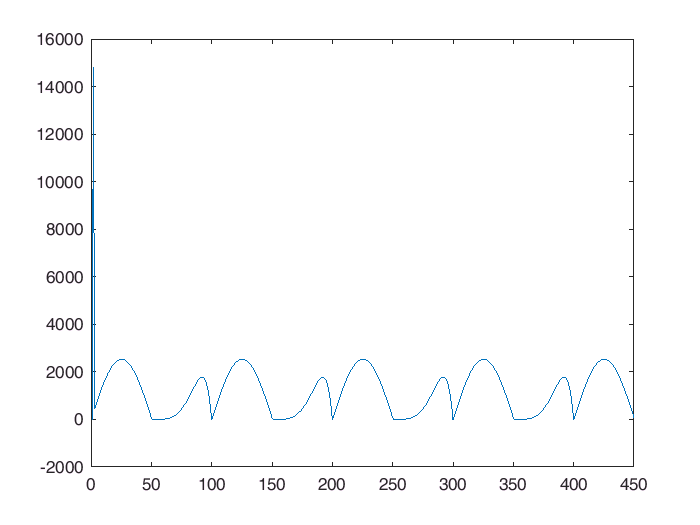

plot(Wdiff);

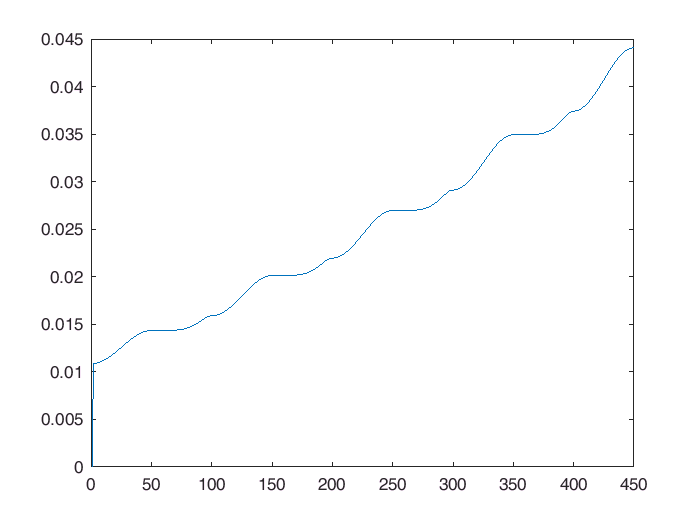

plot(1:n,D(1:n));

% %---------------------stress evolution at 2 scales plot settings-----------------------------
grid on;
grid minor;
set(gca ,'FontSize',20);
hXLabel = xlabel('t(s)' ,'Fontsize' ,20);
hYLabel = ylabel('Stress(Pa)', 'Fontsize' ,20);
hTitle = title('Microscopic stress evolution at 2 scales' ,'Fontsize' ,20);
set(hTitle, 'FontSize', 20, 'FontWeight' , 'bold')
% hLegend=legend([yield1,Sb1,Trial1,yield8,Sb8,Trial8],'(\sigma_y-\lambda\Sigma_H)/s_1     at scale s_1','||S-b||              at scale s_1',...
%     '||S-b||_{trial}         at scale s_1', '(\sigma_y-\lambda\Sigma_H)/s_8     at scale s_{8}','||S-b||              at scale s_{8}','||S-b||_{trial}         at scale s_{8}');
hLegend=legend([yield1,Sb1,Trial1],'(\sigma_y-\lambda\Sigma_H)/s_1     at scale s_1','||S-b||              at scale s_1',...
    '||S-b||_{trial}         at scale s_1');
set([hLegend, gca], 'FontSize', 20)
% Adjust font
set(gca, 'FontName', 'Helvetica')
set([hTitle, hXLabel, hYLabel], 'FontName', 'AvantGarde')
% Adjust axes properties
set(gca, 'Box', 'off', 'TickDir', 'out', 'TickLength', [.02 .02], ...
    'XMinorTick', 'on', 'YMinorTick', 'on', 'YGrid', 'on', ...
    'XColor', [.3 .3 .3], 'YColor', [.3 .3 .3], ...
    'LineWidth', 1)
set(gcf,'color','w'); %set figure background transparent
set(gca,'color','w'); %set axis transparent
% Maximize print figure
set(gcf,'outerposition',get(0,'screensize'));
set(gcf, 'PaperPositionMode', 'manual');
set(gcf, 'PaperUnits', 'points'); %[ {inches} | centimeters | normalized | points ]
set(gcf, 'PaperPosition', [0 0 1920 1080]); %set(gcf,'PaperPosition',[left,bottom,width,height])
% saveas(gcf,'trialsinSmin.png');

